# Sample 7-5

## 幾何学処理

畳み込みの随伴作用素

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Geometric image processing

Adjoint of convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### インパルス応答の生成

(Generation of impulse response)

ftype = "prewitt";
h = rot90(fspecial(ftype),2)

h =     -1    -1    -1
     0     0     0
     1     1     1


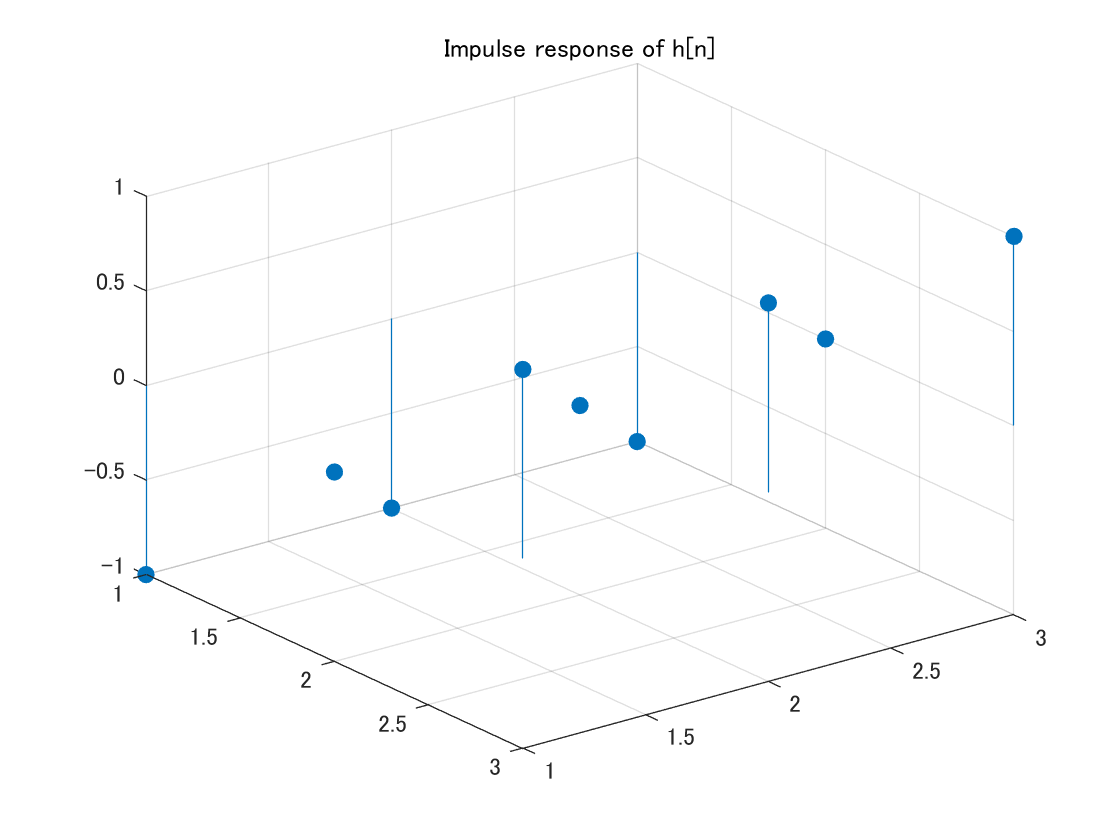

figure(1)
stem3(h,'filled')
axis ij
title('Impulse response of h[n]')

### 二変量循環畳み込みの行列表現

(Matrix representation of bivariate circular convolution)

周期 $\mathbf{Q}$ の循環畳み込み演算 (Circular convolution with period $\mathbf{Q}$)

        
$$\{v[\mathbf{n}]\}_\mathbf{n}=\{h[\mathbf{n}]\}_\mathbf{n} \bigcirc  \{u[\mathbf{n}]\}_\mathbf{n} = \sum_{\mathbf{k}\in\Omega\subset\mathbb{Z}^2}h[\mathbf{k}]\{u[(\!(\mathbf{n}-\mathbf{k})\!)_\mathbf{Q}]\}_\mathbf{n}
$$


% Input array size
N1 =6;
N2 =4;

% Find the matrix representation of the bivariate downsampling
N  = N1*N2;
T = [];
for idx = 1:N
    % Generating a standard basis vector
    e = zeros(N1,N2);
    e(idx) = 1;
    % Response to the standard basis vector
    t = imfilter(e,h,'conv','circ'); 
    T(:,idx) = t(:);
end

行列表現 (Matrix represntation)

- 
$$\mathbf{T}$$


% Matrix representation of the bivariate downsampling
T

T =      0    -1     0     0     0     1     0    -1     0     0     0     1     0     0     0     0     0     0     0    -1     0     0     0     1
     1     0    -1     0     0     0     1     0    -1     0     0     0     0     0     0     0     0     0     1     0    -1     0     0     0
     0     1     0    -1     0     0     0     1     0    -1     0     0     0     0     0     0     0     0     0     1     0    -1     0     0
     0     0     1     0    -1     0     0     0     1     0    -1     0     0     0     0     0     0     0     0     0     1     0    -1     0
     0     0     0     1     0    -1     0     0     0     1     0    -1     0     0     0     0     0     0     0     0     0     1     0    -1
    -1     0     0     0     1     0    -1     0     0     0     1     0     0     0     0     0     0     0    -1     0     0     0     1     0
     0    -1     0     0     0     1     0    -1     0     0     0     1     0    -1     0     0     0     1     0     0     0

### 二変量循環畳み込みの随伴作用素

(Adjoint operator of bivariate circular convolution)

エルミート転置 (Herimitian transposition)

- 
$$\mathbf{T}^H$$


% Adjoint matrix of the bivariate circular convolution
T'

ans =      0     1     0     0     0    -1     0     1     0     0     0    -1     0     0     0     0     0     0     0     1     0     0     0    -1
    -1     0     1     0     0     0    -1     0     1     0     0     0     0     0     0     0     0     0    -1     0     1     0     0     0
     0    -1     0     1     0     0     0    -1     0     1     0     0     0     0     0     0     0     0     0    -1     0     1     0     0
     0     0    -1     0     1     0     0     0    -1     0     1     0     0     0     0     0     0     0     0     0    -1     0     1     0
     0     0     0    -1     0     1     0     0     0    -1     0     1     0     0     0     0     0     0     0     0     0    -1     0     1
     1     0     0     0    -1     0     1     0     0     0    -1     0     0     0     0     0     0     0     1     0     0     0    -1     0
     0     1     0     0     0    -1     0     1     0     0     0    -1     0     1     0     0     0    -1     0     0    

随伴作用素(Adjoint operator)

        
$$T^\ast(\{v[\mathbf{m}]\}_\mathbf{m})=\mathrm{vec}_{\Omega_\mathrm{u}}^{-1} \circ \mathbf{T}^H\mathrm{vec}_{\Omega_\mathrm{v}}(\{v[\mathbf{m}]\}_\mathbf{m})$$


% Adjoint operator T*
adjOp = @(x) reshape(T'*x(:),[N1 N2]);

### 内積の保存の確認

(Confirmation of the preservation of the inner product)

入力配列の生成 (Generation of an input array) 

-  
$$\{u[\mathbf{n}]\}_\mathbf{n}$$


% Generation of an input array u 
arrayU = randn(N1,N2);

  循環畳み込みの出力 (Output of the circular convolution)

- 
$$\{v[\mathbf{m}]\}_\mathbf{m}=T(\{u[\mathbf{n}]\}_\mathbf{n})$$


% Circular convolution (v=Tu)
arrayV = imfilter(arrayU,h,'conv','circ');

任意の出力領域配列生成(Generation of an arbitrary array in output range)

% Array generation in the same domain with arrayV
arrayY = randn(size(arrayV),'like',arrayV);

内積 (Inner product)          

        
$$\alpha=\langle \mathbf{y},\mathbf{v}\rangle=\langle\mathbf{y},\mathbf{Tu}\rangle$$


% Inner product <y,v>=<y,Tu>
innprodA = dot(arrayY(:),arrayV(:))

innprodA = -0.5761

循環畳み込みの随伴作用素 (The adjoint operator of circular convolution)

           
$$\mathbf{r}=\mathbf{T}^H\mathbf{v}$$


% Adjoint operation of circular convolution (r=T'v)
arrayR = adjOp(arrayY)

arrayR =    -2.3182   -1.8764   -2.4241   -1.7791
   -3.6957   -0.3046   -1.7407   -1.5339
    2.8798    5.1064    3.1533    3.1104
   -0.3144    2.0279    1.6786    3.1066
   -0.5616   -3.2301   -0.7292   -1.3313
    4.0100   -1.7233    0.0621   -1.5727


            
$$\beta=\langle \mathbf{r},\mathbf{u}\rangle=\langle\mathbf{T}^H\mathbf{y},\mathbf{u}\rangle$$


% Inner product <r,u>=<T'v,u>
innprodB = dot(arrayR(:),arrayU(:));

% Verify the preservation of the inner product
err = abs(innprodA - innprodB);
disp(['|<y,Tu> - <T''y,u>| = ' num2str(err)])

|<y,Tu> - <T'y,u>| = 3.1086e-15


### 反転インパルス応答による循環畳み込み

(Circular convolution with the reversal impulse response)

         
$$\{r[\mathbf{n}]\}_\mathbf{n}=\{\bar{h}[-\mathbf{n}]\}_\mathbf{n} \bigcirc  \{y[\mathbf{n}]\}_\mathbf{n} = \sum_{\mathbf{k}\in\Omega\subset\mathbb{Z}^2}\bar{h}[-\mathbf{k}]\{y[(\!(\mathbf{n}-\mathbf{k})\!)_\mathbf{Q}]\}_\mathbf{n}
$$


% Revaersal impulse response
f = conj(rot90(h,2))

f =      1     1     1
     0     0     0
    -1    -1    -1


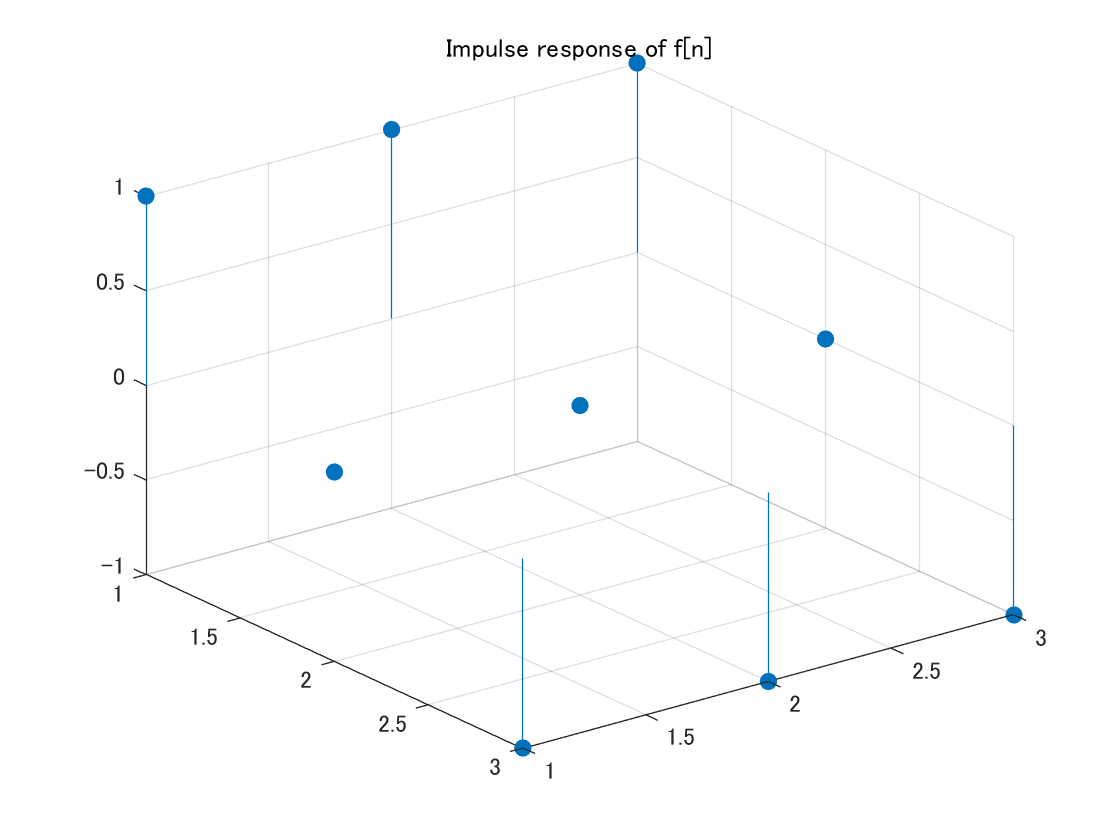

figure(2)
stem3(f,'filled')
axis ij
title('Impulse response of f[n]')


% Circular convolution with impulse response f
arrayS = imfilter(arrayY,f,'conv','circ')

arrayS =    -2.3182   -1.8764   -2.4241   -1.7791
   -3.6957   -0.3046   -1.7407   -1.5339
    2.8798    5.1064    3.1533    3.1104
   -0.3144    2.0279    1.6786    3.1066
   -0.5616   -3.2301   -0.7292   -1.3313
    4.0100   -1.7233    0.0621   -1.5727


行列演算とIMFILTERの比較

% Definition of MSE
mymse = @(x,y) sum((x-y).^2,'all')/numel(x);

% Evaluation
disp(['MSE between matrix operation and IMFILTER: ' num2str(mymse(arrayR,arrayS))])

MSE between matrix operation and IMFILTER: 1.3382e-31


© Copyright, Shogo MURAMATSU, All rights reserved.